## Optimize Live Editor Task

% Create optimization variables
x1 = optimvar("x1","LowerBound",-2,"UpperBound",2);
x2 = optimvar("x2","LowerBound",-2,"UpperBound",2);

% Set initial starting point for the solver
initialPoint.x1 = zeros(size(x1));
initialPoint.x2 = zeros(size(x2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = 100*(x2 - x1^2)^2 + (1 - x1)^2;

% Set nondefault solver options
options = optimoptions("ga","MaxStallGenerations",100,"PlotFcn",...
    "gaplotbestf");

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       x1, x2

	minimize :
       ((100 .* (x2 - x1.^2).^2) + (1 - x1).^2)


	variable bounds:
       -2 <= x1 <= 2

       -2 <= x2 <= 2



Solving problem using ga.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


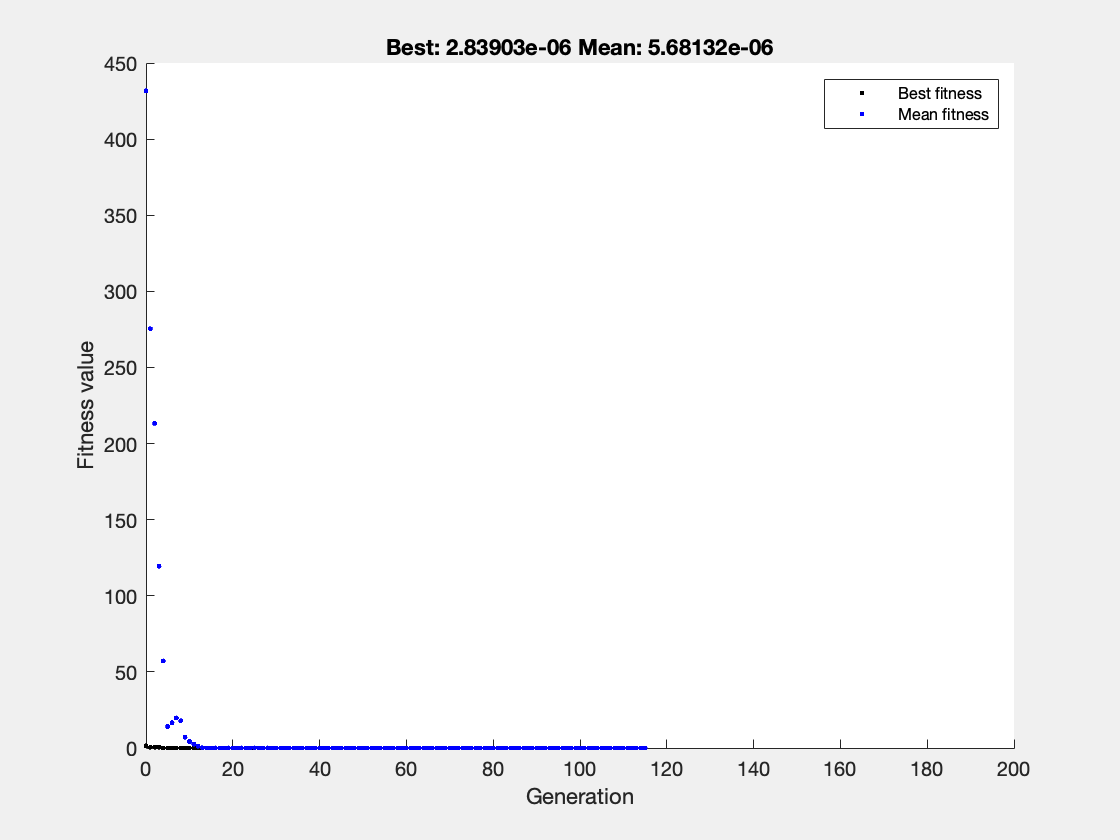


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","ga","Options",options);


% Display results
solution

solution = struct with fields:
    x1: 0.9983
    x2: 0.9966


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = 2.8390e-06


% Clear variables
clearvars x1 x2 initialPoint options reasonSolverStopped objectiveValue